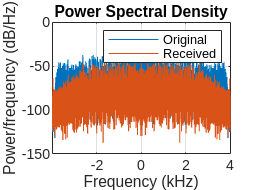

Quiz Q1 – SNR_out (no extra noise): -0.1 dB


clear all;

[wav1, fs] = audioread("song1.wav");
[wav4, ~] = audioread("sound32265398.wav");

% Truncate to the same length
N = min(length(wav1), length(wav4));
s = wav1(1:N);
r = wav4(1:N);

% Compute error
e = r - s;

% Compute SNR_out in dB
snr_out = 10 * log10(sum(s.^2) / sum(e.^2));

% Plot

figure;
hold on;
periodogram(s, [], [], fs, 'centered');
periodogram(r, [], [], fs, 'centered');
title('Power Spectral Density');
xlabel('Frequency (kHz)');
ylabel('Power/frequency (dB/Hz)');
legend('Original', 'Received');

% Display result
fprintf('Quiz Q1 – SNR_out (no extra noise): %.1f dB\n', snr_out);


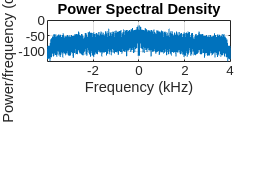

figure;
subplot(2, 1, 1);
hold on;
periodogram(wav1, [], [], fs, 'centered');

% [wav6, fs] = audioread("sound19919663.wav");
% periodogram(wav6, [], [], fs, 'centered');
% hold off;
% subplot(2, 1, 2);
[wav7, fs] = audioread("sound56184030.wav");

Error using audioread>readaudio (line 161)
The filename specified was not found in the MATLAB path.

Error in audioread (line 154)
    [y, Fs] = readaudio (filename, fileNameObj.RemoteFileName, range, datatype);

periodogram(wav7, [], [], fs, 'centered');
hold off;

figure;
hold on;
plot(wav1);
plot(wav4);
plot(wav5);
plot(wav6);
legend('orig', 'trans');
hold off;
% Ex 1.3: 40dB
% Ex 1.5: Trans power: -10->0, Recv gain: 30->60

clear all;
[wav, fs] = audioread("song2.wav");
periodogram(wav, [], [], fs, 'centered');

clear all;
[wav, fs] = audioread("song3.wav");
periodogram(wav, [], [], fs, 'centered');
